pcdDir = "/Volumes/Expansion/Calibration/ecal_meas/2023-02-04_16-18-06.097_wildpose_v1.1/lidar/";
pcdFileNames = [
"livox_frame_1675520286_140565712.pcd"
"livox_frame_1675520286_240604656.pcd"
"livox_frame_1675520286_340648848.pcd"
"livox_frame_1675520286_440659248.pcd"
"livox_frame_1675520286_540656592.pcd"
"livox_frame_1675520286_640659376.pcd"
"livox_frame_1675520286_740608208.pcd"
"livox_frame_1675520286_840677424.pcd"
"livox_frame_1675520286_940759664.pcd"
]

pcdFileNames = 9×1 string array
    "livox_frame_1675520286_140565712.pcd"
    "livox_frame_1675520286_240604656.pcd"
    "livox_frame_1675520286_340648848.pcd"
    "livox_frame_1675520286_440659248.pcd"
    "livox_frame_1675520286_540656592.pcd"
    "livox_frame_1675520286_640659376.pcd"
    "livox_frame_1675520286_740608208.pcd"
    "livox_frame_1675520286_840677424.pcd"
    "livox_frame_1675520286_940759664.pcd"


## Merge

% Initialize ptCloud using the first file
filepath = fullfile(pcdDir, pcdFileNames(1));
ptCloud = pcread(filepath);

% Load and merge the next set of point clouds
for i = 2:length(pcdFileNames)
    filepath = fullfile(pcdDir, pcdFileNames(i));
    tmpPtCloud = pcread(filepath);
    ptCloud = pcmerge(ptCloud, tmpPtCloud, 0.001); % Using a merge tolerance of 0.001, adjust accordingly
end

pcwrite( ...
    ptCloud, ...
    fullfile( ...
        "/Users/ikuta/Documents/Projects/wildpose-applications/results/", ...
        "merge_00.pcd" ...
   ) ...
)

## Visualization

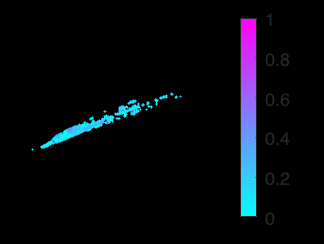

pcshow(ptCloud.Location, ptCloud.Intensity / max(ptCloud.Intensity))
title(filepath, 'Interpreter','none')
xlabel("X")
ylabel("Y")
zlabel("Z")
colorbar
colormap("cool")